Problem 1

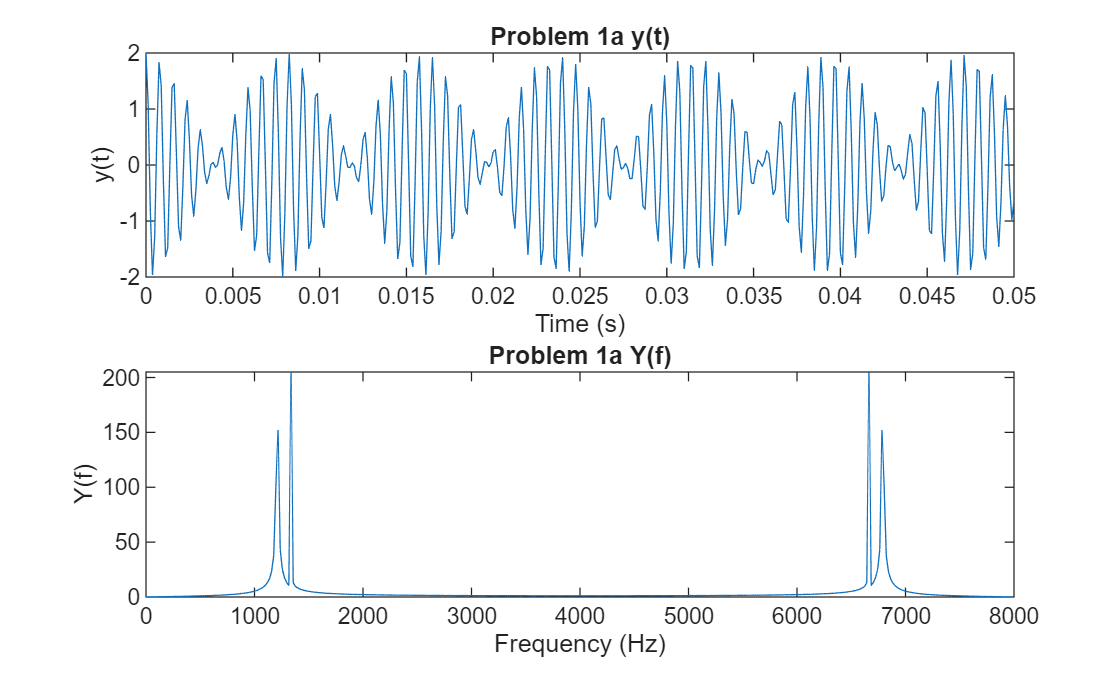

fs = 8000; % in Hz
dt = 1/fs;
t = 0:dt:0.05;
f1 = 1209; % in Hz
f2 = 1336; % in Hz

% original
y = cos(2*pi*f1*t) + cos(2*pi*f2*t);
Y = fft(y);
N = length(Y);
f = (0:N-1)*(fs/N);

figure;

subplot(2, 1, 1) % time
plot(t, y)
title('Problem 1a y(t)');
xlabel('Time (s)');
ylabel('y(t)');

subplot(2, 1, 2) % freq
plot(f, abs(Y))
title('Problem 1a Y(f)');
xlabel('Frequency (Hz)');
ylabel('Y(f)');

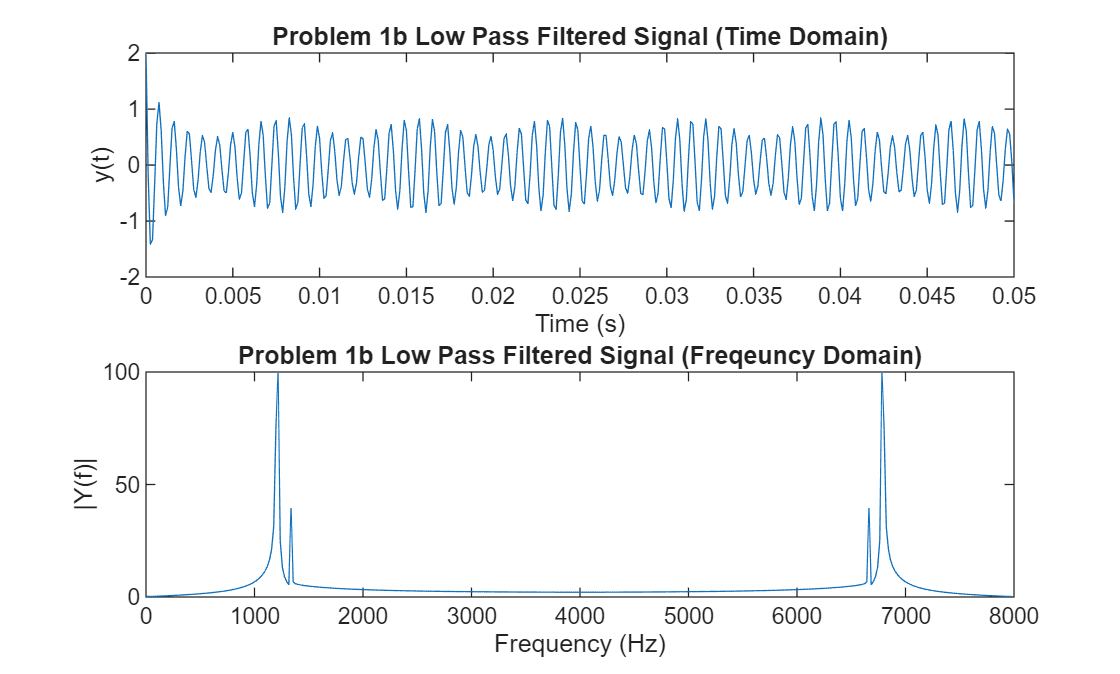


% LPF
fc = 1250;
Wn = fc / (fs / 2);

[b, a] = butter(10, Wn, 'low');
y_LPF = filtfilt(b, a, y);
N = length(y);
f = (0:N-1)*(fs/N);
Y = fft(y);
Y_LPF = fft(y_LPF);

figure;

subplot(2, 1, 1) % time LPF
plot(t, y_LPF)
title('Problem 1b Low Pass Filtered Signal (Time Domain)');
xlabel('Time (s)');
ylabel('y(t)');

subplot(2, 1, 2) % freq LPF
plot(f, abs(Y_LPF))
title('Problem 1b Low Pass Filtered Signal (Freqeuncy Domain)');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

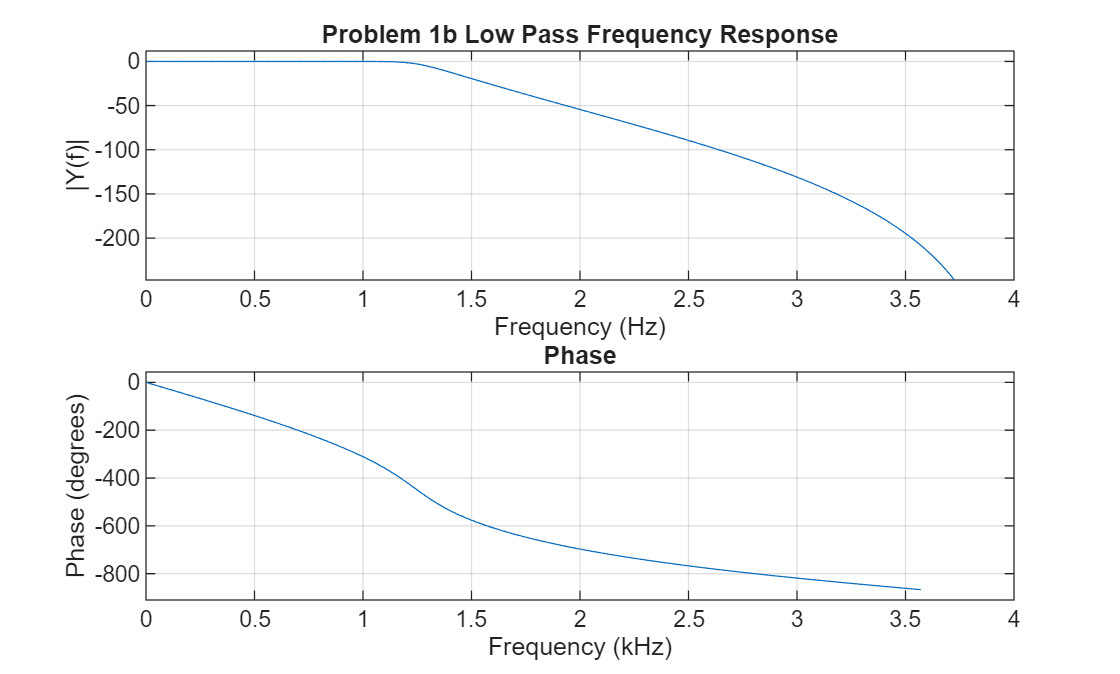


figure;

% LPF Freq Response
freqz(b,a,[],fs)
subplot(2, 1, 1)
title('Problem 1b Low Pass Frequency Response');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

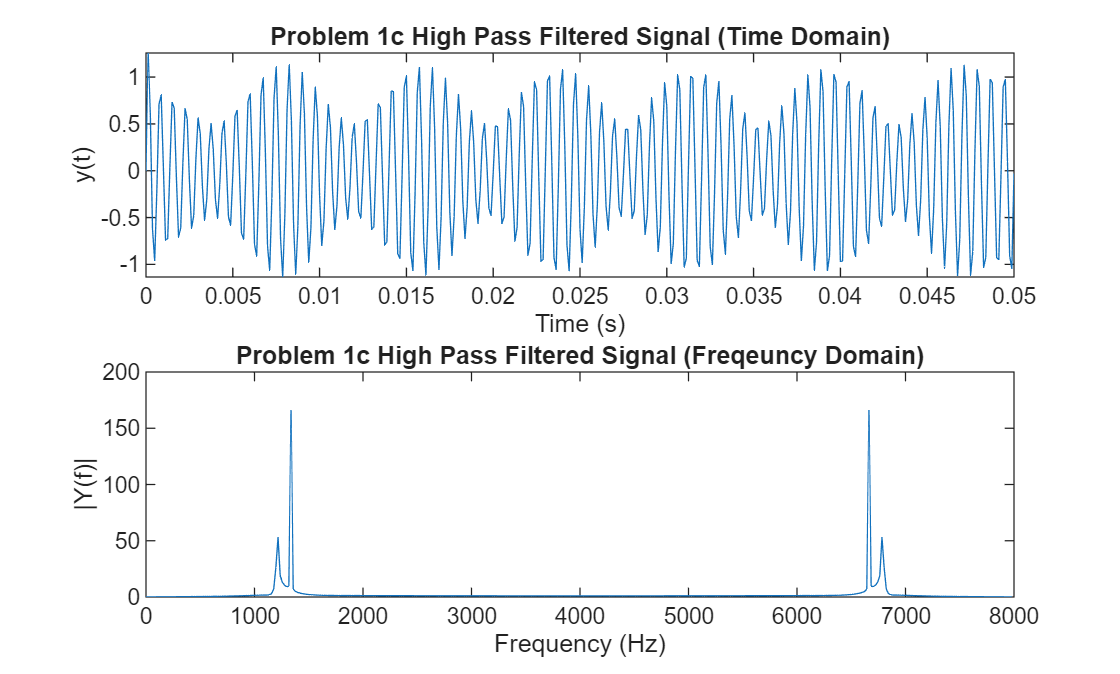


% HPF
fc = 1250;
Wn = fc / (fs / 2);

[b, a] = butter(10, Wn, 'high');
y_HPF = filtfilt(b, a, y);
N = length(y);
f = (0:N-1)*(fs/N);
Y = fft(y);
Y_HPF = fft(y_HPF);

figure;

subplot(2, 1, 1) % time HPF
plot(t, y_HPF)
title('Problem 1c High Pass Filtered Signal (Time Domain)');
xlabel('Time (s)');
ylabel('y(t)');

subplot(2, 1, 2) % freq HPF
plot(f, abs(Y_HPF))
title('Problem 1c High Pass Filtered Signal (Freqeuncy Domain)');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

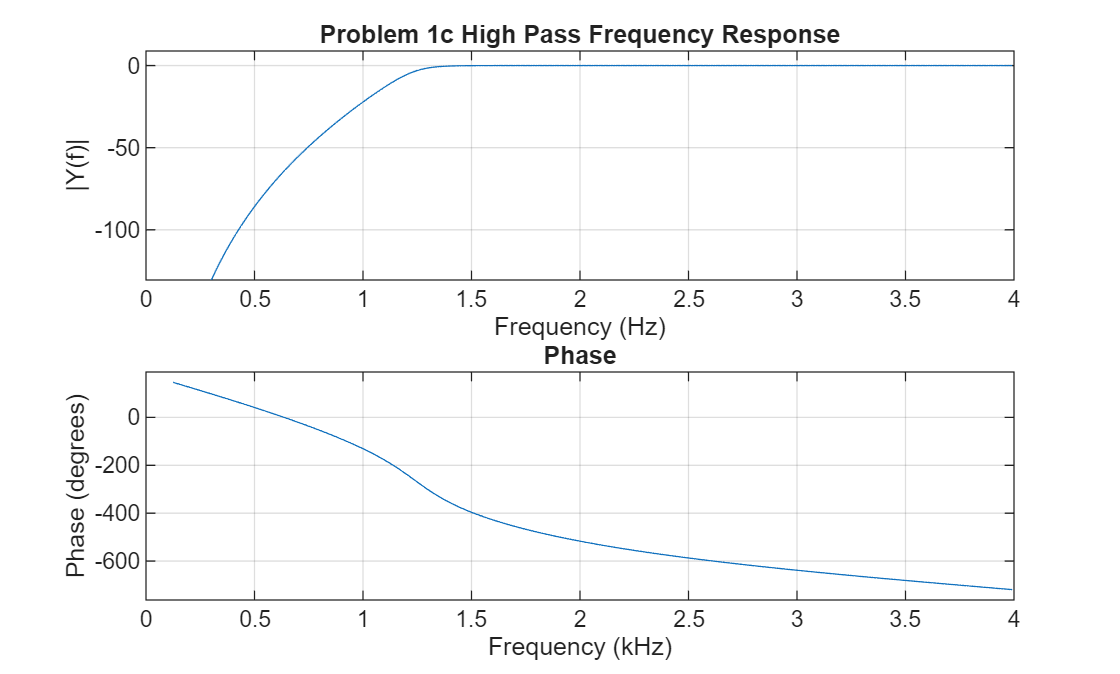


figure;

% HPF Freq Response
freqz(b,a,[],fs)
subplot(2, 1, 1)
title('Problem 1c High Pass Frequency Response');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

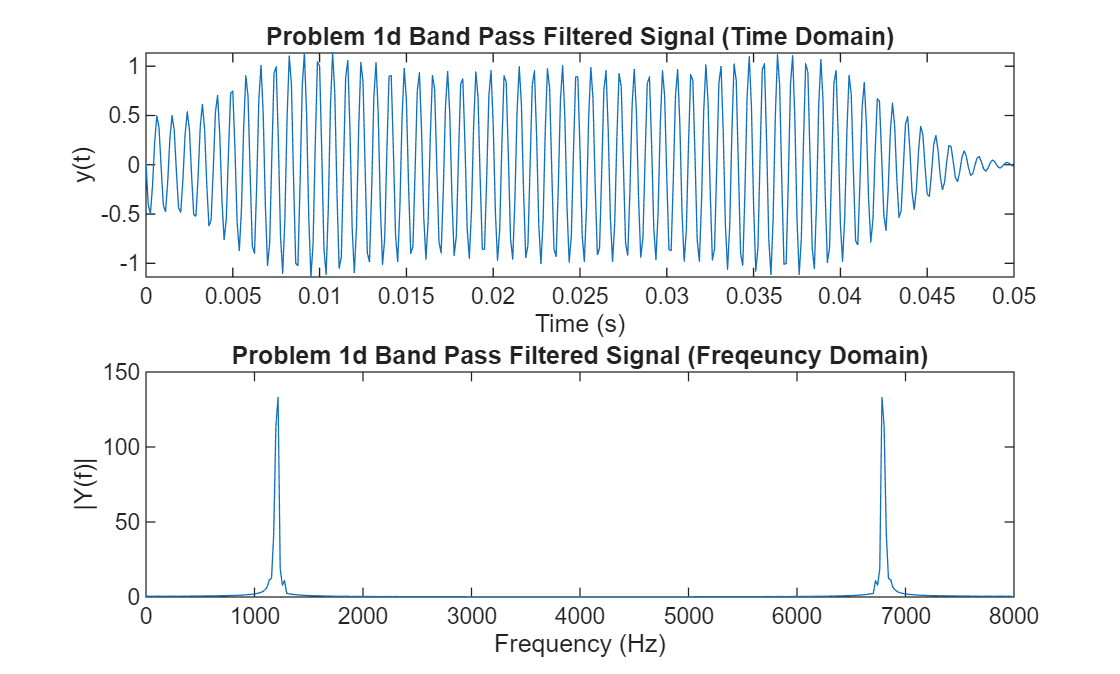


% BPF
f_low = 1150;
f_high = 1275;
Wn = [f_low f_high] / (fs / 2);

[b, a] = butter(6, Wn, 'bandpass');
y_BPF = filtfilt(b, a, y);
N = length(y);
f = (0:N-1)*(fs/N);
Y = fft(y);
Y_BPF = fft(y_BPF);

figure;

subplot(2, 1, 1) % time BPF
plot(t, y_BPF)
title('Problem 1d Band Pass Filtered Signal (Time Domain)');
xlabel('Time (s)');
ylabel('y(t)');

subplot(2, 1, 2) % freq BPF
plot(f, abs(Y_BPF))
title('Problem 1d Band Pass Filtered Signal (Freqeuncy Domain)');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

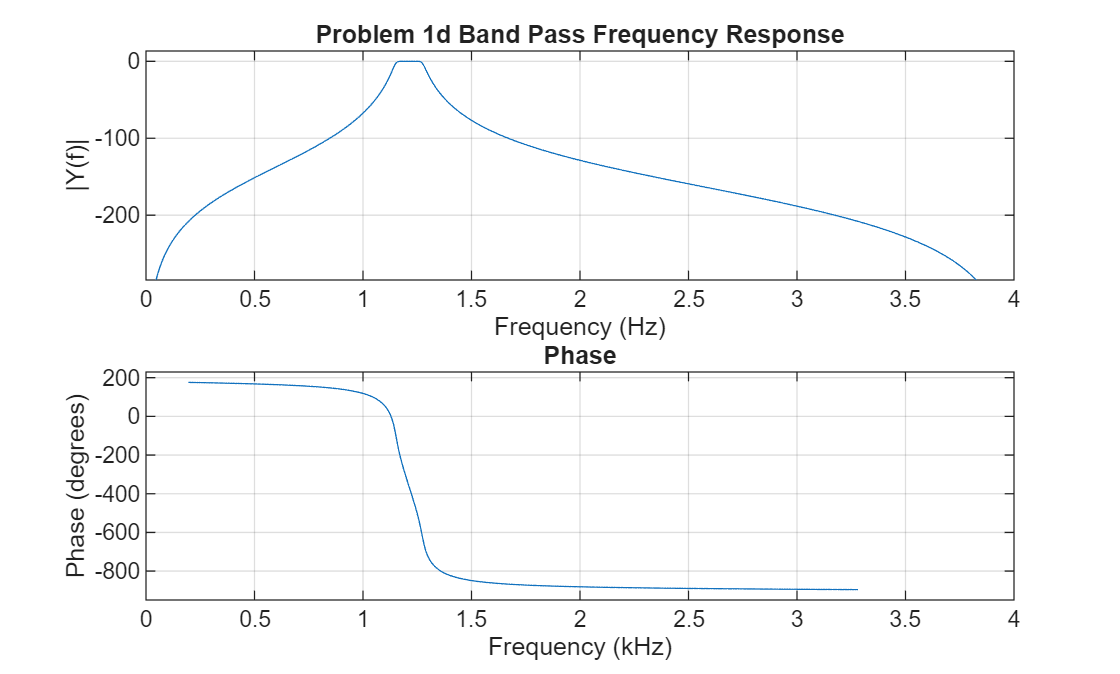


figure;

% BPF Freq Response
freqz(b,a,[],fs)
subplot(2, 1, 1)
title('Problem 1d Band Pass Frequency Response');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

Problem 2

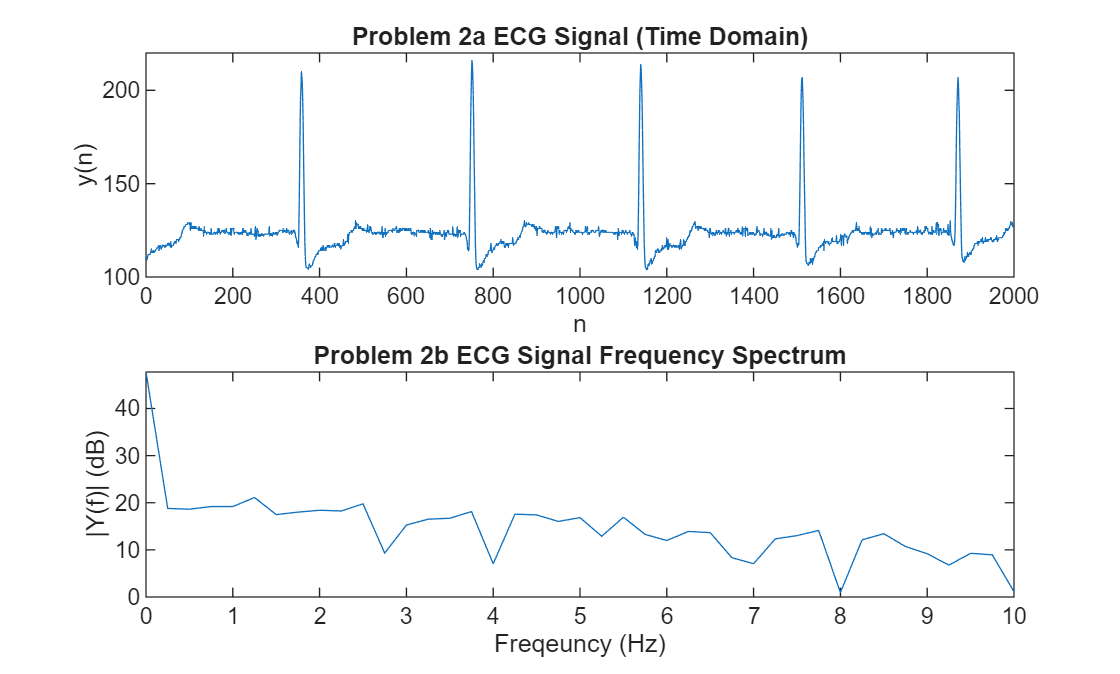

fs = 512; % in Hz

load('SAMPLE_ECG.mat')
y = ECG_Data;
N = length(y);
n = 0:N-1;
t = n/fs;

Y = fft(y)/N;
f = (0:N-1)*(fs/N);

figure;

subplot(2, 1, 1)
plot(n, y)
axis([0 2000 100 220]);
title('Problem 2a ECG Signal (Time Domain)');
xlabel('n');
ylabel('y(n)');

[pxx, f] = periodogram(y, [], [], fs);

subplot(2, 1, 2)
plot(f, 10*log10(pxx))
xlim([0 10])
title('Problem 2b ECG Signal Frequency Spectrum');
xlabel('Freqeuncy (Hz)');
ylabel('|Y(f)| (dB)');


[pks,locs] = findpeaks(y, 'MinPeakHeight', 160);
peakTimes = locs/fs; % locations to time

rr = diff(peakTimes);
bpm = 60./rr;
average_bpm = mean(bpm)

average_bpm = 81.3228

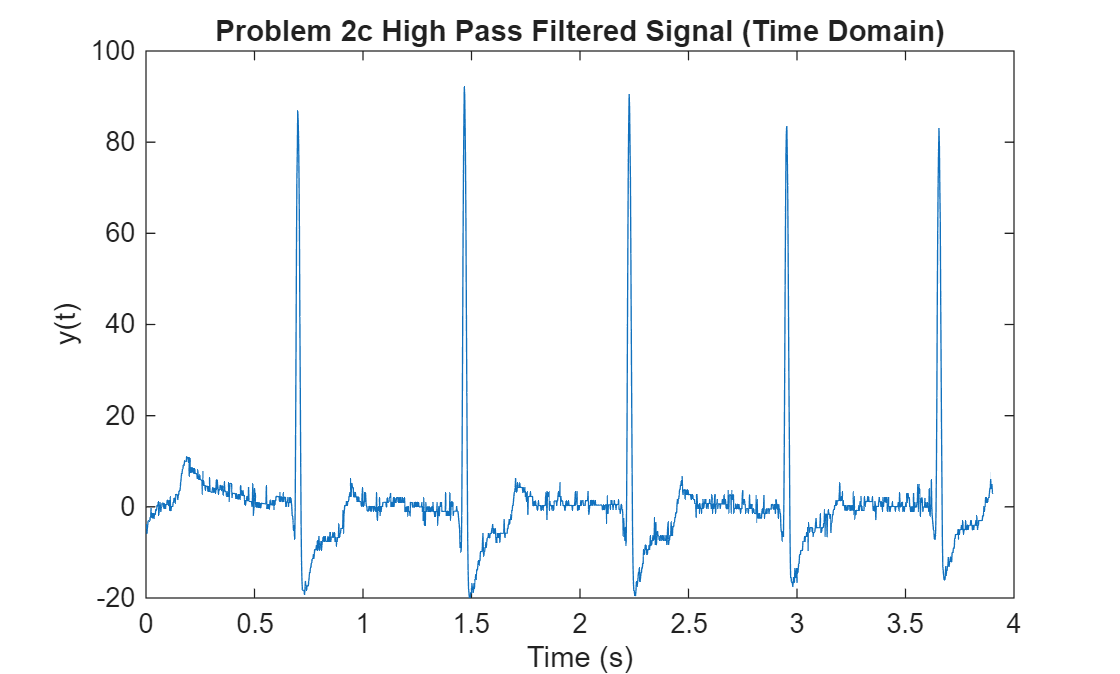


% HPF
fc = 0.5; % in Hz
Wn = fc / (fs / 2);

[b, a] = butter(2, Wn, 'high');
y_HPF = filtfilt(b, a, y);
N = length(y);
f = (0:N-1)*(fs/N);
Y = fft(y);
Y_HPF = fft(y_HPF)/N;

figure;

plot(t, y_HPF)
title('Problem 2c High Pass Filtered Signal (Time Domain)');
xlabel('Time (s)');
ylabel('y(t)');

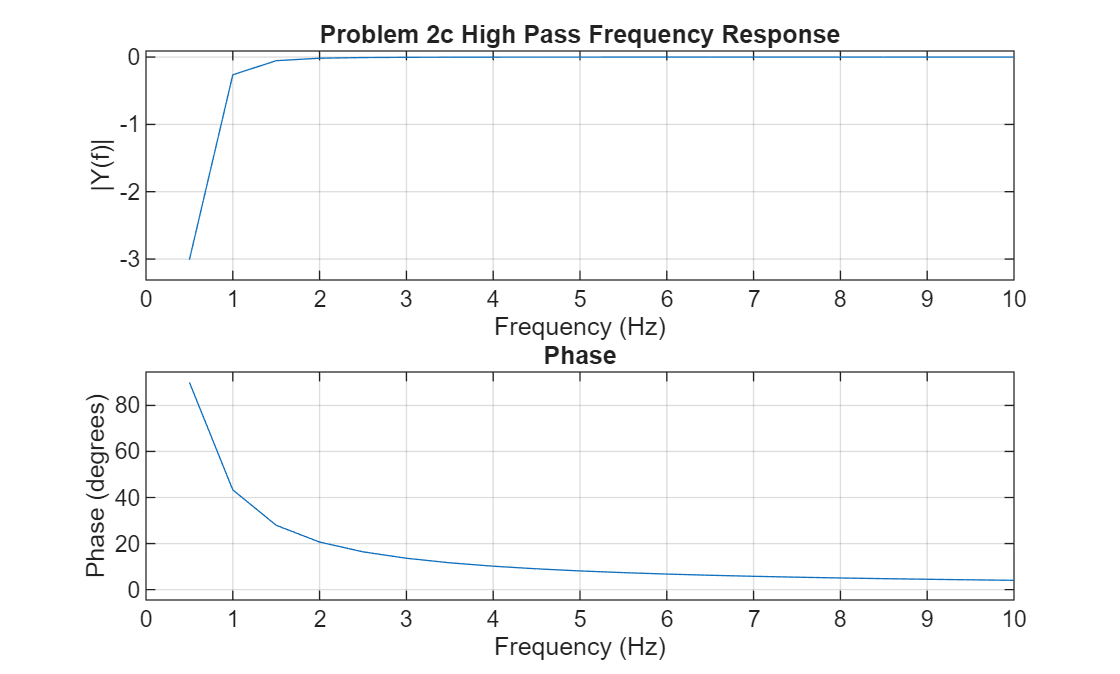


figure;

% HPF Freq Response
freqz(b,a,[],fs)
subplot(2, 1, 1)
xlim([0 10]);
title('Problem 2c High Pass Frequency Response');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
subplot(2, 1, 2)
xlim([0 10]);

Problem 3

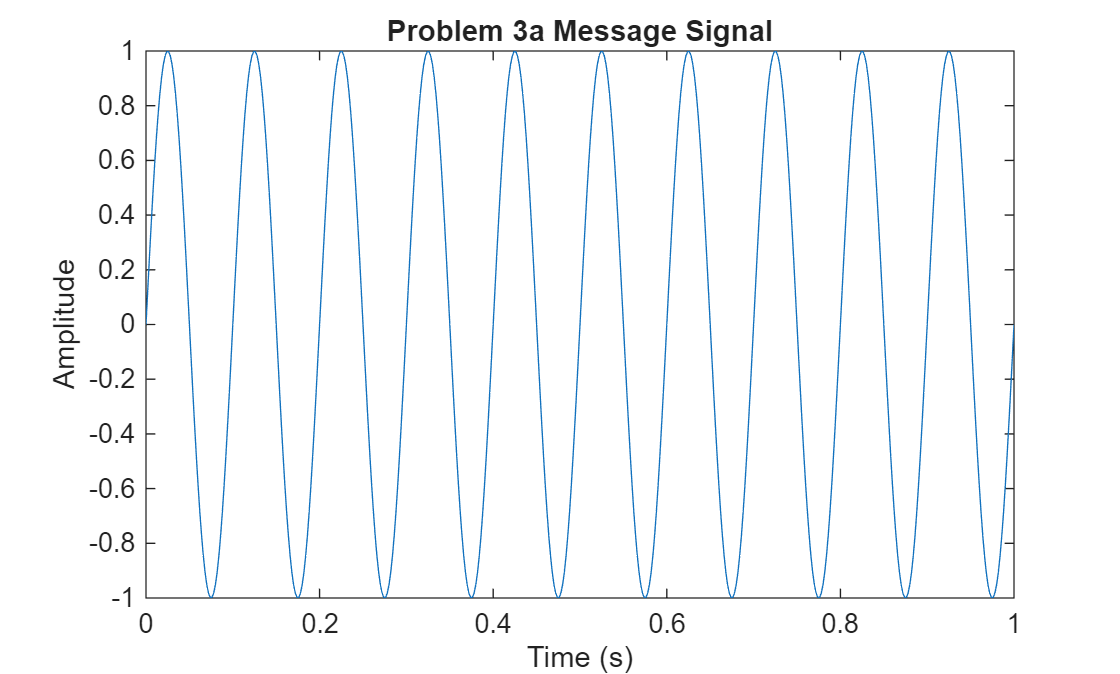

fs = 500; % in Hz
dt = 1/fs;
t = 0:dt:1;
f1 = 10; % in Hz;

figure;

msg  = sin(2*pi*f1*t);
plot(t, msg)
title('Problem 3a Message Signal');
xlabel('Time (s)');
ylabel('Amplitude');

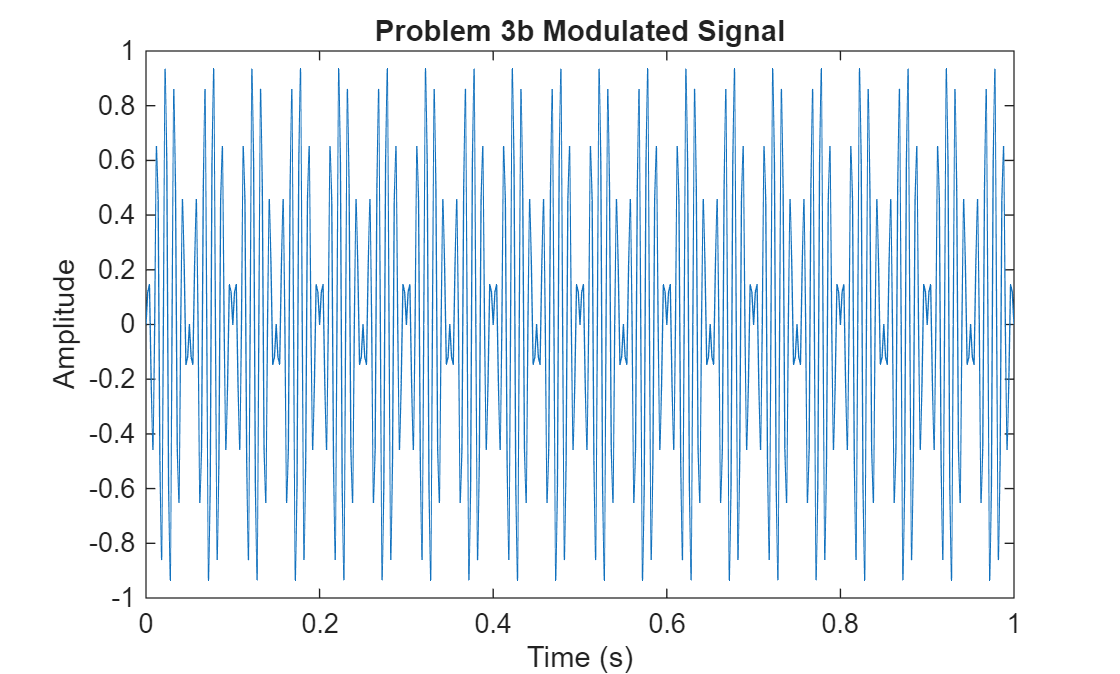


figure;

mod = my_ammod(msg, t);
plot(t, mod)
title('Problem 3b Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

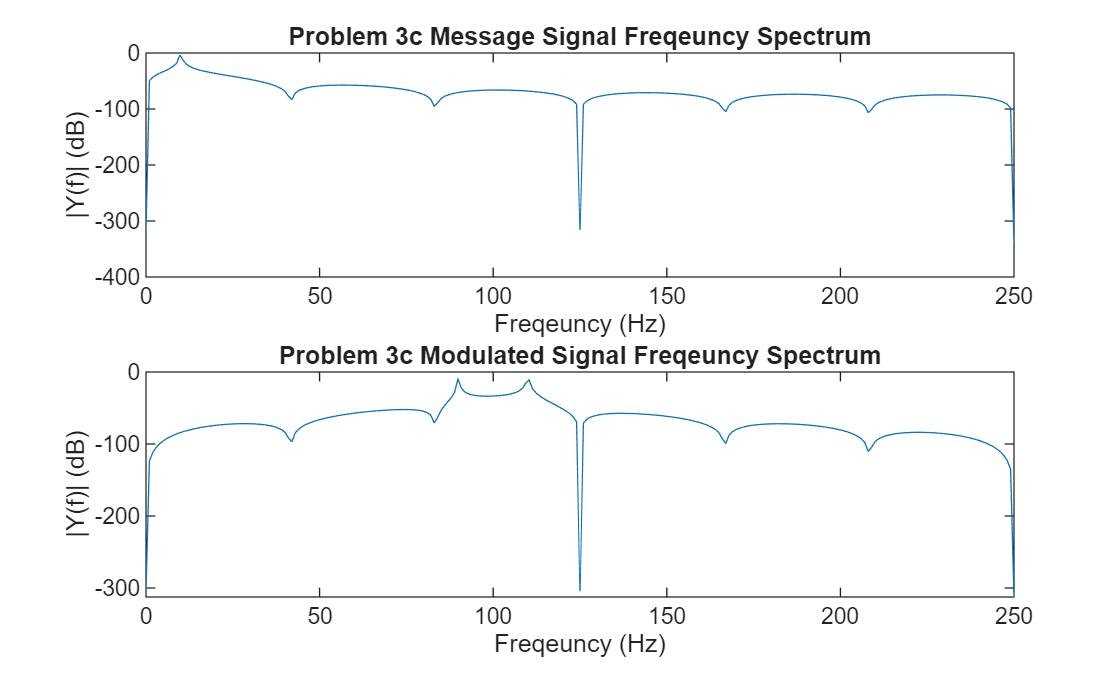


[pxx, f] = periodogram(msg, [], [], fs);

figure; 

subplot(2, 1, 1)
plot(f, 10*log10(pxx))
title('Problem 3c Message Signal Freqeuncy Spectrum');
xlabel('Freqeuncy (Hz)');
ylabel('|Y(f)| (dB)');

[pxx, f] = periodogram(mod, [], [], fs);

subplot(2, 1, 2)
plot(f, 10*log10(pxx))
title('Problem 3c Modulated Signal Freqeuncy Spectrum');
xlabel('Freqeuncy (Hz)');
ylabel('|Y(f)| (dB)');

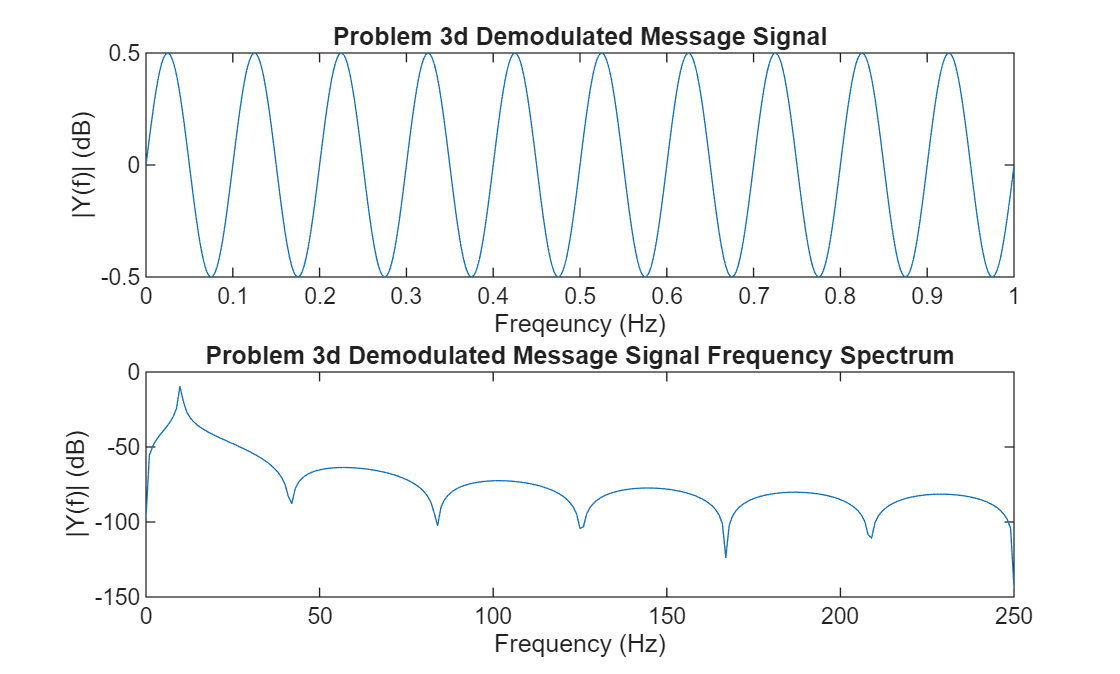


% The message and modulated signals have very similar frequency spectrums with 
% subtle but important differences. They both have a significant dip at roughly 125 Hz.
% The message signal has a spike at 10 Hz, the frequency of the message, as
% expected.
% The modulated signal has peaks at roughly 90 and 110 Hz. These peaks seem
% to be at the modulated signal's freqeuncy +- the message signal
% freqeuncy.

demod = my_amdemod(mod, t, fs);

figure;

subplot(2, 1, 1)
plot(t, demod)
title('Problem 3d Demodulated Message Signal');
xlabel('Freqeuncy (Hz)');
ylabel('|Y(f)| (dB)');

[pxx, f] = periodogram(demod, [], [], fs);

subplot(2, 1, 2)
plot(f, 10*log10(pxx))
title('Problem 3d Demodulated Message Signal Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('|Y(f)| (dB)');


% The message and demodulated signal plots are very similar.
% The only difference in the time domain plots is the amplitude. In the
% message plot the amplitude is 1 whereas the demodulated signal has an
% amplitude of 0.5. The freqeuncy remained the same at 10 Hz.
% The freqeuncy spectrum plots also differ by a factor of 1/2.
% Additionally, the downward spike moved from about 125 Hz in the message
% signal plot to about 160 Hz.


Problem 3 Functions

function y = my_ammod(msg, t)
    fc = 100; % carrier signal in Hz
    carrier = sin(2*pi*fc*t);
    y = msg.*carrier;
end

function y = my_amdemod(mod, t, fs)
    fc = 100; % carrier freq in Hz
    carrier = sin(2*pi*fc*t);
    mixed = mod.*carrier;
    fcut = 50; % cuttof freq in Hz
    Wn = fcut/(fs/2);
    [b, a] = butter(4, Wn, 'low');
    y = filtfilt(b, a, mixed);
    
end